# Using Emscripten with MATLAB Coder App

This example shows how to use the Emscripten toolchain in the [MATLAB Coder](https://www.mathworks.com/help/coder/ref/matlabcoder-app.html) app to compile an array addition function into web assembly code. The generated code then runs in the browser in a locally hosted web page.

## Create a MATLAB Function

Create a sample MATLAB function from which we will generate code. The sample function, `foo`, shown here adds two fixed-length arrays on a per-element basis and returns an equal length array.

## Launch the MATLAB Coder App

Launch the MATLAB Coder app and follow the instructions to add the foo.m function as the entry-point function. Use the **Autodefine Input Types** to specify the inputs types as `double(1x3)`.

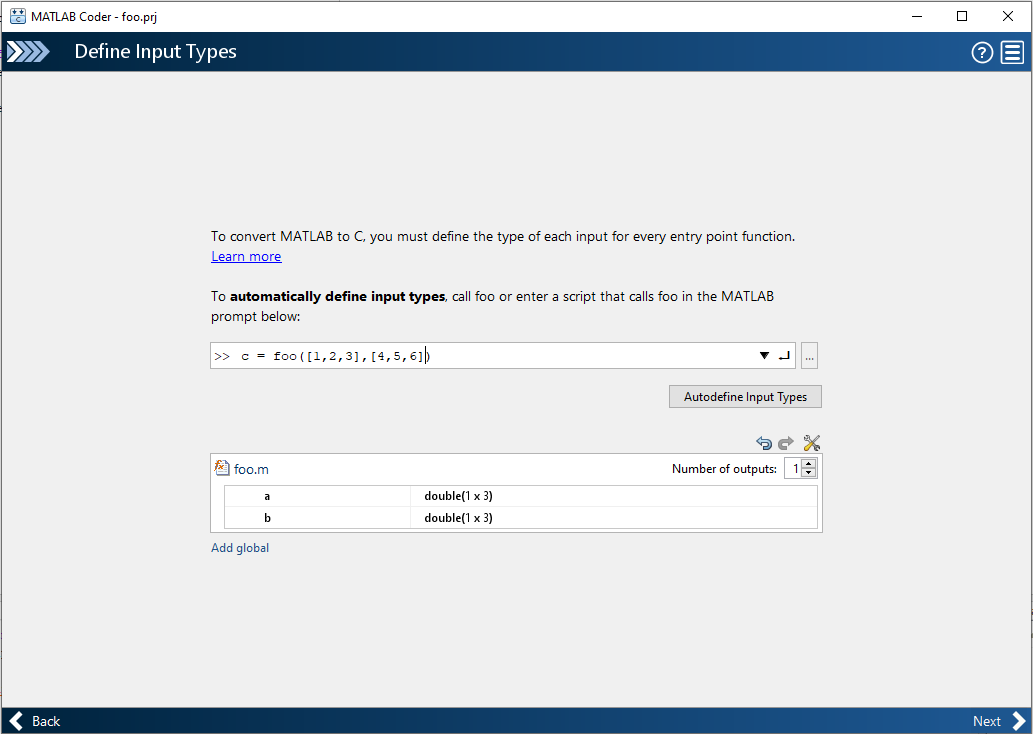

In the Generate Code panel, set the parameters as shown.

- **Build type** — `Dynamic Library`

- **Langauge** — `C++`

- **Interface style** — `Functions`

- **Hardware Board** — `None - Select device below`

- **Device vendor** — `Google`

- **Device type** — `V8 Engine`

- **Toolchain** — `Emscripten v2.0.26 | gmake (64-bit Windows)`

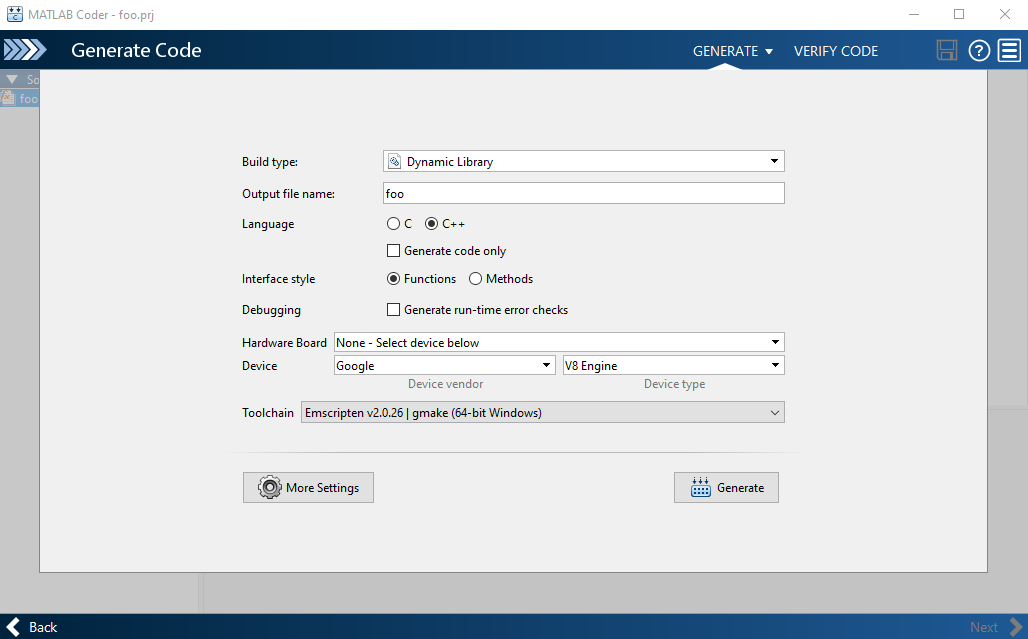

In **More Settigns > All Settings**, find and set the **Post-code-generation command** parameter to `wasm.coder.postcodegen.addCLinkage(buildInfo); wasm.coder.postcodegen.registerExportedFunctions(buildInfo)`. This adds C linkage to C++ functions to prevent name mangling and registers the entrypoint functions to be exported and accessible to the JavaScript environment.

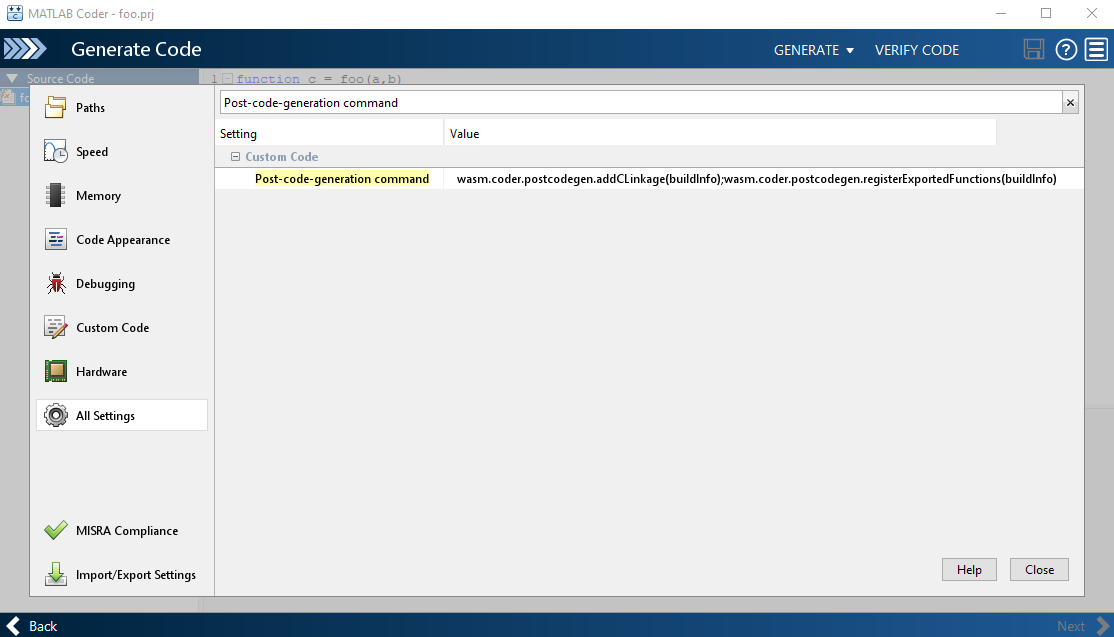

Click the **GENERATE** button to start the code generation process. When the build process completes, the output files, `foo.js` and `foo.wasm`, get generated into the codegen/dll/foo directory.

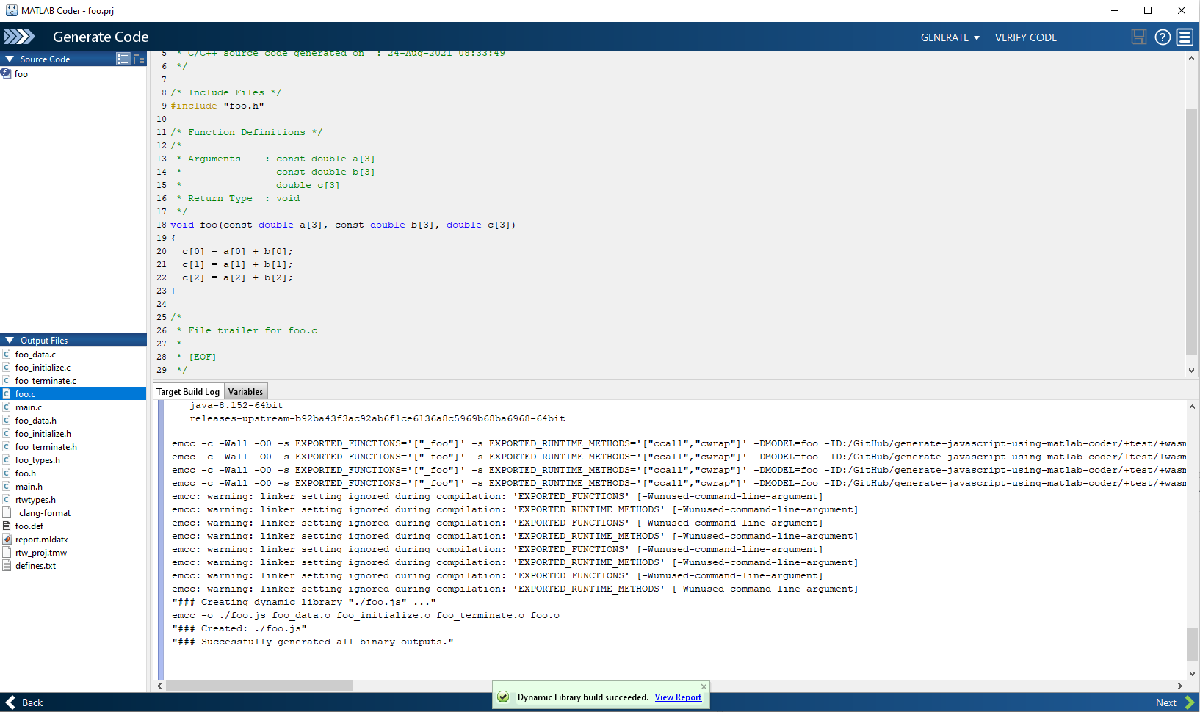

## Run the Generated Function

Use the following HTML with JavaScript code to test the generated function.

You can then run a development server to wasm.utilities.DevelopmentServer class, as shown in this code.

server = wasm.utilities.DevelopmentServer("Directory",pwd,"Port",8000);
server.start();

Development Server serving directory 'D:\Github\MATLAB\Others\HXML\A' at locations:
    http://100.124.139.6:8000
    http://10.7.51.194:8000
    http://192.168.137.1:8000
    http://localhost:8000



url = 'http://localhost:8000/index1.html';
web(url, '-browser')




server.stop();

In a modern web browser, you can open the app by navigating to this IP address: [http://localhost:8000](http://localhost:8000). After the web page opens as a blank screen, open the browser developer tools by pressing **Ctrl+Shift+i**. The Console window displays the output generated in the JavaScript calls to your function, `foo`.